# Lesson 37 - Example 37.5

Solve the Dirichlet problem using the FD method

$u_{\textrm{xx}} +u_{\textrm{yy}} =0$ for 0<x<1 and 0<y<1

with 

u=0 On top and sides of square

$u\left(x,0\right)=\sin \left(\pi \;x\right)$ for $0\le x\le 1$

Letting $u\left(x_j ,y_i \right)=u_{i,j}$ as developed in the text, and class, we can discretize the PDE and BCs as in (37.6)


$$u_{i+1,j} +u_{i-1,j} +u_{i,j+1} +u_{i,j-1} -4u_{\textrm{ij}} =0$$


where we have assumed a uniform grid discretization in both the x and y directions.  

Let N denote the number of grid points in the x direction, and similarly in the y direction (since we chose uniform grid size).

Then, the BCs become:


$$\begin{array}{l}
u\left(x_j ,y_N \right)=u_{\textrm{Nj}} =0\;\;\left(\textrm{top}\;\textrm{side}\;\textrm{of}\;\textrm{square}\right)\\
u\left(x_1 ,y_i \right)=u_{\textrm{i1}} =0\;\left(\textrm{left}\;\;\textrm{side}\;\textrm{of}\;\textrm{square}\right)\\
u\left(x_N ,y_i \right)=u_{\textrm{iN}} =0\;\left(\textrm{right}\;\textrm{side}\;\textrm{of}\;\textrm{square}\right)\\
u\left(x_j ,y_1 \right)=u_{1j} =\sin \left(\pi \;x_j \right)\left(\textrm{bottom}\;\textrm{of}\;\textrm{square}\right)
\end{array}$$


Writing out the equations for N points in either direction we can notice a pattern (try with N=6, i.e. 4 interior points).  

Do on your own or see notes:

Let the solution vector be organized as follows:


$$\left[\begin{array}{c}
u_{2,2}\\
u_{3,2}\\
\vdots\\
u_{N-1,2}\\
u_{2,3}\\
u_{3,3}\\
\vdots\\
u_{N-1,3}\\
\vdots\\
\vdots\\
\vdots\\
u_{2,N-1}\\
u_{3,N-1}\\
\vdots\\
u_{N-1,N-1}\\
\end{array}\right]$$


which essentially is a "straight out" or "vectorized" version of the interior of the main u(x,y) grid.

Define the number of points N.

clear all; clc; close all;

N = 5; % number of grid points in x and y directions, same in both.
m = N - 2; % number of interior points


Build the grid.

% -------------------------------------------------------------------------
% Define the grid:
% -------------------------------------------------------------------------
x1 = 0;
xN = 1;
y1 = 0;
yN = 1;
% -------------------------------------------------------------------------
% Determine the stepsize:
% -------------------------------------------------------------------------
h       = (xN-x1)/(N-1);
% -------------------------------------------------------------------------
% We'll just use the same stepsize in x and y 
% Build the xvector of grid points:
% -------------------------------------------------------------------------
x       = x1:h:xN;
y       = y1:h:yN;

Initialize the solution matrix

% -------------------------------------------------------------------------
% Define the solution matrix and plug in BCs.
% -------------------------------------------------------------------------
sol_FD         = zeros(N,N);
sol_FD(:,1)    = 0; % Enforcing the left side is u=0
sol_FD(:,end)  = 0; % Enforcing right side u=0
sol_FD(end,:)  = 0; % Enforcing the top u=0
sol_FD(1,:)    = sin(pi*x); % Enforcing the bottom BC u(x,0)=sin(pi*x)
% -------------------------------------------------------------------------

Build the operator matrix

% -------------------------------------------------------------------------
% Build the matrix A:
% -------------------------------------------------------------------------
e=1*(ones(m^2-1,1));
mth_adj = e.*(mod(ind,3)~=0)'; % since every third one should be 0
% Build the main structure of the matrix
A = -2*eye(m^2,m^2) ...  % places -4 on the main diagonal
    + 1*diag(mth_sup_adj,1) ... % Places the adjusted ones on the superdiagonal
    + 1*diag(mth_sup_adj,-1) ... % Places the adjusted ones on the subdiagonal 
    + 1*diag(ones(m^2-m,1),m) ... % Places ones on the mth superdiagonal (no adjustments needed for this.
    + 1*diag(ones(m^2-m,1),-m);  % Places ones on the mth subdiagonal (no adjustments needed for this.




Let's take a peek at the matrix and see if the structure is what we expect.

A

A =     -2     1     0     1     0     0     0     0     0
     1    -2     1     0     1     0     0     0     0
     0     1    -2     0     0     1     0     0     0
     1     0     0    -2     1     0     1     0     0
     0     1     0     1    -2     1     0     1     0
     0     0     1     0     1    -2     0     0     1
     0     0     0     1     0     0    -2     1     0
     0     0     0     0     1     0     1    -2     1
     0     0     0     0     0     1     0     1    -2



% -------------------------------------------------------------------------
% Build the RHS vector
% -------------------------------------------------------------------------
RHS_vec     = zeros(m^2,1);
% Adjust the entries that have the BCs in them 1, m+1, 2*m+1, etc.  Note
% that the book uses a different ordering of the EQUATIONS that is not as 
% directly compatible with the (:) notation.

for k=1:m
    RHS_vec((k-1)*m + 1)  = -sol_FD(1,k);
end

% -------------------------------------------------------------------------
% Solve for the solution at the interior points
% -------------------------------------------------------------------------
u_interior                      = A\RHS_vec(:);
u_interior                      = reshape(u_interior,m,m); 
sol_FD(2:(end-1),2:(end-1))     = u_interior;



Plot the result:

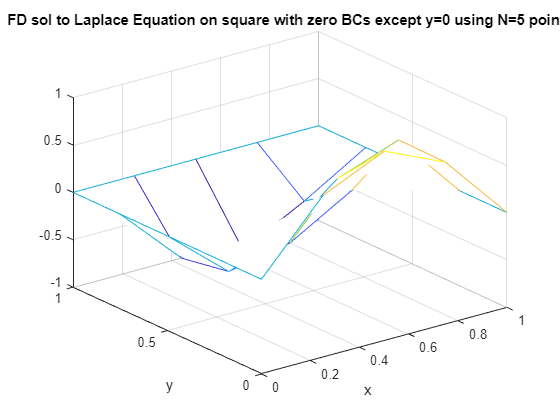

figure; 
mesh(x,y,sol_FD);
xlabel('x')
ylabel('y')
title(['FD sol to Laplace Equation on square with zero BCs except y=0 using N=' num2str(N) ' points'])

Notice that you do in fact see the plot in the way you'd expect with sin(x) along the bottom row corresponding to y=0.

Try running this with more points.  Notice we could also just write a function that computes this for us for any number of given points.

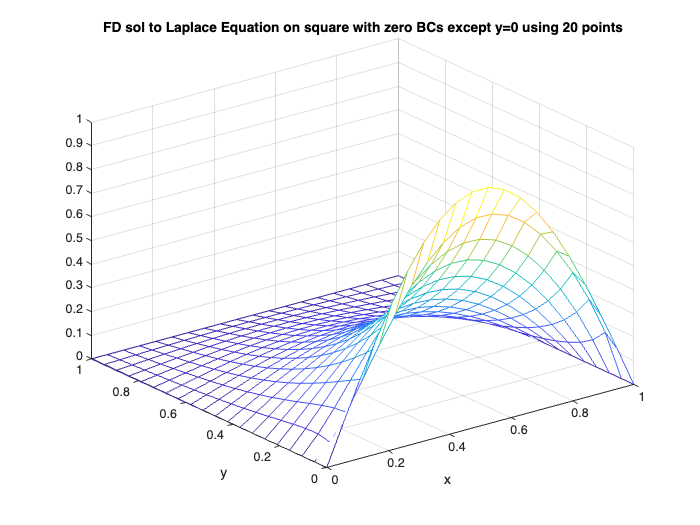

numpts = 20;
[sol_new,xnew,ynew] = FD_2D_Lesson37_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['FD sol to Laplace Equation on square with zero BCs except y=0 using ' num2str(numpts) ' points'])